program

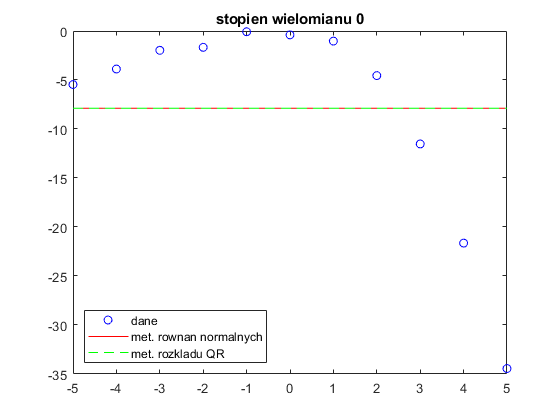

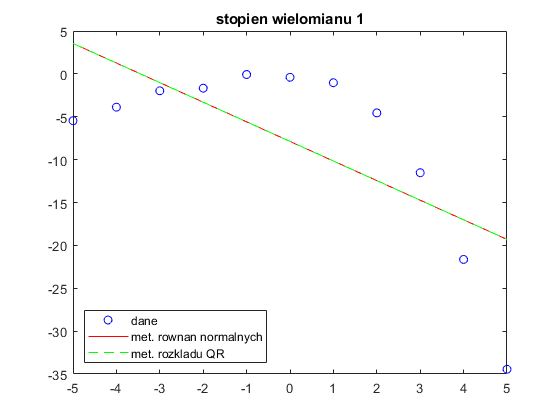

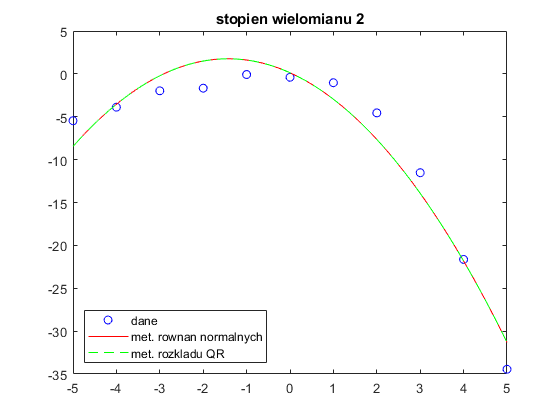

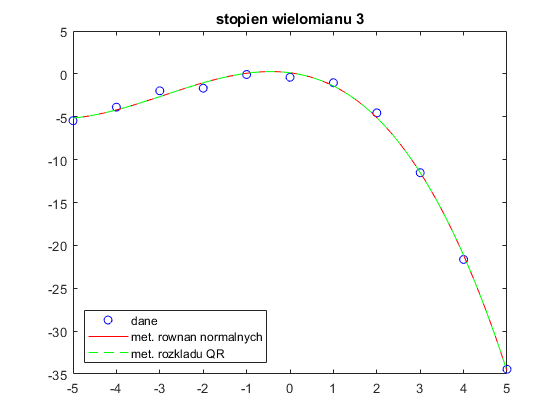

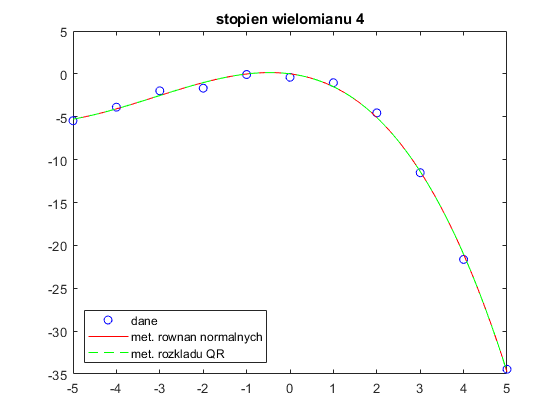

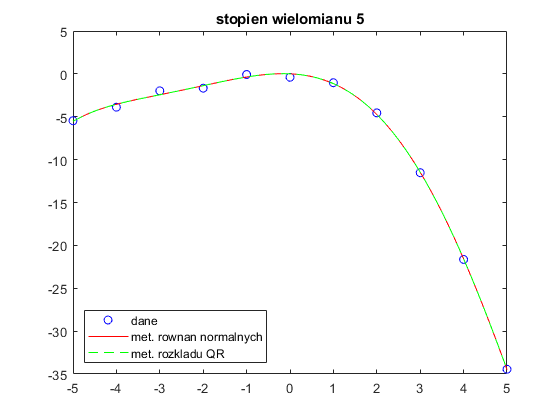

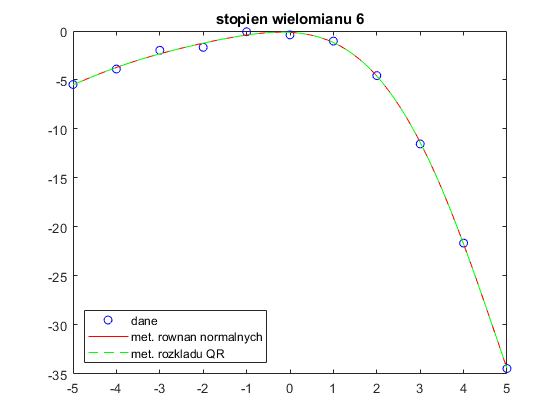

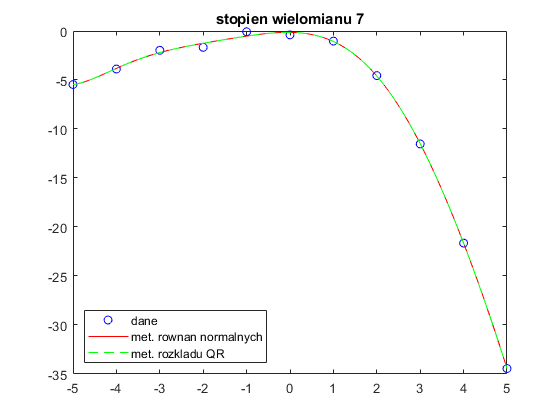

clc;
clear;
dane = [-5 -5.4606;-4 -3.8804;-3 -1.9699;-2 -1.6666;-1 -0.0764;0 -0.3971;1 -1.0303;2 -4.5483;3 -11.528;4 -21.6417;5 -34.4458];
x = linspace(-5,5,100);
max_stopien = 8;

norma_res = zeros(max_stopien);
norma_res = norma_res(:,1:2);

for stopien = 0:max_stopien
    figure
    funkcja = uklad_rownan_normalnych(dane, stopien);
    y = fun(funkcja, x);
    funkcja2 = uklad_qr(dane, stopien);
    y2 = fun(funkcja2, x);
    plot(dane(:,1),dane(:,2),'bo', x, y, 'r', x, y2, 'g--');
    legend({'dane','met. rownan normalnych','met. rozkladu QR'},'Location','southwest');
    title(['stopien wielomianu ' num2str(stopien)]);
    norma_res(stopien+1,1) = norm(dane(:,2) - fun(funkcja, dane(:,1)));
    norma_res(stopien+1,2) = norm(dane(:,2) - fun(funkcja2, dane(:,1)));
end


norma_res

norma_res =    34.3326   34.3326
   24.5832   24.5832
    7.3647    7.3647
    1.4390    1.4390
    1.3958    1.3958
    0.8501    0.8501
    0.7595    0.7595
    0.7069    0.7069
    0.6997    0.7181


**funkcje pomocnicze**

uklad rownan normalnych

function wspolczynniki = uklad_rownan_normalnych(dane, st_wielomianu)
   % wyznaczanie macierzy Grama - <przeksztalcenie_i,przeksztalcenie_j>
    [r_wiersze, r_kolumny] = size(dane);
    st_wielomianu = st_wielomianu + 1;
    macierz_Grama = wyzn_macierz_Grama(dane, st_wielomianu);
    
   % wektor prawej strony
    prawa_strona = zeros(st_wielomianu);
    prawa_strona = prawa_strona(:,1);
    for i = 1:st_wielomianu
        for k = 1:r_wiersze
            prawa_strona(i) = prawa_strona(i) + (dane(k,1))^(i-1)*dane(k,2);
        end
    end
    
    wspolczynniki = macierz_Grama\prawa_strona;
end

uklad wynikajacy z rozkladu QR

function wspolczynniki = uklad_qr(dane, st_wielomianu)
   % wyznaczanie macierzy Grama - <przeksztalcenie_i,przeksztalcenie_j>
    [r_wiersze, r_kolumny] = size(dane);
    st_wielomianu = st_wielomianu + 1;
    macierz_Grama = wyzn_macierz_Grama(dane, st_wielomianu);
    
   % wektor prawej strony
    prawa_strona = zeros(st_wielomianu);
    prawa_strona = prawa_strona(:,1);
    for i = 1:st_wielomianu
        for k = 1:r_wiersze
            prawa_strona(i) = prawa_strona(i) + (dane(k,1))^(i-1)*dane(k,2);
        end
    end
    
    [Q R] = qr_rozklad(macierz_Grama);
    wspolczynniki = R\Q'*prawa_strona;
end


wyznaczenie macierzy Grama

function macierz_Grama = wyzn_macierz_Grama(dane, st_wielomianu)
   % wyznaczanie macierzy Grama - <przeksztalcenie_i,przeksztalcenie_j>
    macierz_Grama = zeros(st_wielomianu);
    [r_wiersze, r_kolumny] = size(dane);
    for i = 1:st_wielomianu
        for j = 1:st_wielomianu
            for k = 1:r_wiersze
                macierz_Grama(i,j) = macierz_Grama(i,j) + (dane(k,1))^(i+j-2);
            end
        end
    end
end

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = fun(funkcja, x)
    [temp rozmiar_x] = size(x);
    if rozmiar_x == 1
        x = x';
        rozmiar_x = temp;
    end
    st_wielomianu = size(funkcja);
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        for j = 1:st_wielomianu
            y(i,1) = y(i,1) + funkcja(j,1)*(x(1,i))^(j-1);
        end
    end
end

rozklad QR

function [Q R] = qr_rozklad(A)
     [r_wiersze r_kolumny] = size(A);
     Q = zeros(r_wiersze);
     if r_wiersze > r_kolumny
        R = eye(r_wiersze);
        Q = eye(r_wiersze);
     else
        R = eye(r_kolumny);
        Q = eye(r_wiersze);
     end
    %Gram-Schmidt
     for i = 1:r_kolumny
         Q(:,i) = A(:,i);
         for j = 1:(i-1)
             R(j,i) = mydot(Q(:,j),A(:,i))/mydot(Q(:,j),Q(:,j));
             Q(:,i) = Q(:,i) - R(j,i)*Q(:,j);
         end
     end
     Q = Q(1:r_wiersze,1:r_kolumny);
     %normalizacja
     N = zeros(r_wiersze);
     for i = 1:r_kolumny
         N(i,i) = norm(Q(:,i));
         Q(:,i) = Q(:,i)/N(i,i);
     end
     R = N*R;
     
     if r_wiersze > r_kolumny
        R = R(1:r_kolumny,1:r_kolumny);
     else
        R = R(1:r_wiersze,1:r_wiersze);
     end
end

autorska implementacja matlabowej funkcji dot()

function md = mydot(A,B)
    rozmiar = size(A);
    md = 0;
    for i = 1:rozmiar
        md = md + A(i)*B(i);
    end
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

[https://www.wolframalpha.com/input/?i=-0.09-0.8*x-0.65*x%5E2%2B0.13*x%5E3](https://www.wolframalpha.com/input/?i=-0.09-0.8*x-0.65*x%5E2%2B0.13*x%5E3)

[https://mycurvefit.com/](https://mycurvefit.com/)

         -5               -5.5        

         -4               -3.88       

         -3               -1.97       

         -2               -1.666      

         -1               -0.0764     

          0               -0.397      

          1               -1          

          2               -4.55       

          3              -11.5        

          4              -21.65       

          5              -34.45       

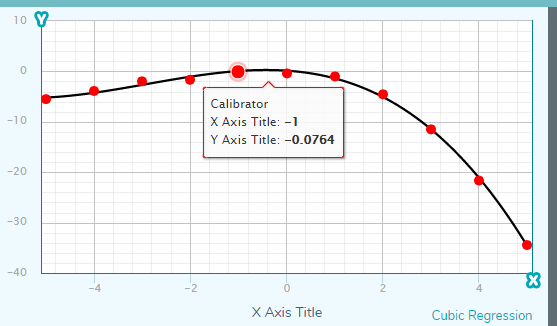

trzeci stopien^

rysowanie funkcji -> ok